## Acuity Grouped Analysis

- loops through all participants in the data folder assigned by script user

- grabs average of last 15 trials 

- creates a data table/cell array that holds variables of interest: untrained and trained thresholds for pre and post assessments

- creates graphs: a box plot of individual differences in each training type and side, a bar graph of each individual performance pre and post training

clear;
clc;
% add path where the data lives
prompt = {'Script User'};
answer = inputdlg(prompt);

%if they say nothing do nothing
if isempty(answer)
    return;
else

    user =  answer{1,1};
    [SubjectDirectory] = UserPath(user);
end
addpath(genpath(cd));
addpath(genpath(SubjectDirectory));


% load in the participant assignment table, with all the subject info
ParticipantAssignment = readtable("ParticipantAssignmentsUAB_corr.csv");
ParticipantAssignmentUCR = readtable("ParticipantAssignmentsUCR_corr.csv");
ParticipantAssignment = [ParticipantAssignment; ParticipantAssignmentUCR];

% use this to find out which participants have finished (everyone that has
% finished should be in your data folder above).

% k is a counter, it counts. use this to loop through your table and add new
% rows
k = 1;

% make counters for each training type as well. this will increase with
% every instance of a person doing each training type

tt1count = 1;
tt2count = 1;
tt3count = 1;

% make a blank table, where we'll save all the important variables. make a
% table for the entire group as well as groups separated by training type.
DataTableAcuity = [];
DataTableAcuityTT1 = [];
DataTableAcuityTT2 = [];
DataTableAcuityTT3 = [];


% loop through the
% participant column in the assignment table

for z = 5:size(ParticipantAssignment,1)
    subjectID = char(ParticipantAssignment.participant(z));

    % make sure the subject is downloaded to your computer, you won't have
    % everyone until we have finished everyone

    % make sure the subject folder exists for the current index (this
    % condition is only met for participant's that have been downloaded to
    % your local folder)

    if exist([SubjectDirectory subjectID]) == 7

        % find the path where the pre-assessment data lives
        directoryPathPre = [SubjectDirectory subjectID '/pre'];

        % grab the mat file you want, it will have a tag called "AcuityPixx"
        FileNameAcuityPre = dir([directoryPathPre '/' subjectID 'AcuityPixx*.mat']);
        FileNameAcuityPre = FileNameAcuityPre.name;
        load(FileNameAcuityPre);

        % from Acuity we want the average of last 15 trials


        Thresholds_Left = Threshlist(1,:,:);
        Thresholds_Left = reshape(Thresholds_Left, [1 60]);
        Thresholds_Right = Threshlist(2,:,:);
        Thresholds_Right = reshape(Thresholds_Right, [1 60]);

        Thresholds_Left_AVG_Last15 =  mean(Thresholds_Left(end-15:end));
        Thresholds_Right_AVG_Last15 = mean(Thresholds_Right(end-15:end));



        % Use the participant assignment table to find out the current
        % participant's trained side. use that info to send the data at each side
        % to the "trained" or "untrained" column later on

        TrainedSide = char(ParticipantAssignment.TRL(z));
        if TrainedSide == 'R'
            TrainedThresholds = Thresholds_Right_AVG_Last15;
            UntrainedThresholds = Thresholds_Left_AVG_Last15;
        elseif TrainedSide == 'L'
            TrainedThresholds = Thresholds_Left_AVG_Last15;
            UntrainedThresholds =  Thresholds_Right_AVG_Last15;
        else
        end

        TrainingType = string(double(ParticipantAssignment.TrainingTask(z)));
        if TrainingType == '1'
            DataTableAcuityTT1{tt1count,1} = subjectID;
            DataTableAcuityTT1{tt1count,2} = TrainedThresholds;
            DataTableAcuityTT1{tt1count,3} = UntrainedThresholds;


        elseif TrainingType == '2'
            DataTableAcuityTT2{tt2count,1} = subjectID;
            DataTableAcuityTT2{tt2count,2} = TrainedThresholds;
            DataTableAcuityTT2{tt2count,3} = UntrainedThresholds;

        elseif TrainingType == '3'
            DataTableAcuityTT3{tt3count,1} = subjectID;
            DataTableAcuityTT3{tt3count,2} = TrainedThresholds;
            DataTableAcuityTT3{tt3count,3} = UntrainedThresholds;

        else
        end



        DataTableAcuity{k,1} = subjectID;
        DataTableAcuity{k,2} = TrainedThresholds;
        DataTableAcuity{k,3} = UntrainedThresholds;


        % i am dumb and cannot think of a way to save these as a table without error so
        % we are doing CELLS, so make the note of which column applies to
        % which variable

        % AcuityPre Trained = Column 2
        % AcuityPre Untrained = Column 3

        % now that you're done with the pre data, clear it out (everything
        % but the subjectID, DataTableAcuity and the counters, we need those)

        clearvars -except  SubjectDirectory DataTableAcuity DataTableAcuityTT1 DataTableAcuityTT2 DataTableAcuityTT3 ParticipantAssignment k z tt1count tt2count tt3count subjectID



Post-Data: You want to do pretty much the same as above but now with the post-training data. 

        directoryPathPost = [SubjectDirectory subjectID '/post'];
        FileNameAcuityPost = dir([directoryPathPost '/' subjectID 'AcuityPixx*.mat']);
        FileNameAcuityPost = FileNameAcuityPost.name;

        load(FileNameAcuityPost);


        % from Acuity we want the average of last 15 trials

        Thresholds_Left = Threshlist(1,:,:);
        Thresholds_Left = reshape(Thresholds_Left, [1 60]);
        Thresholds_Right = Threshlist(2,:,:);
        Thresholds_Right = reshape(Thresholds_Right, [1 60]);

        Thresholds_Left_AVG_Last15 =  mean(Thresholds_Left(end-15:end));
        Thresholds_Right_AVG_Last15 = mean(Thresholds_Right(end-15:end));

        % we also want to decipher which side they were trained on

        TrainedSide = char(ParticipantAssignment.TRL(z));
        if TrainedSide == 'R'
            TrainedThresholds = Thresholds_Right_AVG_Last15;
            UntrainedThresholds = Thresholds_Left_AVG_Last15;
        elseif TrainedSide == 'L'
            TrainedThresholds = Thresholds_Left_AVG_Last15;
            UntrainedThresholds =  Thresholds_Right_AVG_Last15;
        else
        end


        % there's no need to save the subject ID again, so it's been commented
        % out


        TrainingType = string(double(ParticipantAssignment.TrainingTask(z)));
        if TrainingType == '1'
            % DataTableAcuityTT1{tt1count,1} = subjectID;
            DataTableAcuityTT1{tt1count,4} = TrainedThresholds;
            DataTableAcuityTT1{tt1count,5} = UntrainedThresholds;
            tt1count = tt1count + 1;

        elseif TrainingType == '2'
            %DataTableAcuityTT2{tt2count,1} = subjectID;
            DataTableAcuityTT2{tt2count,4} = TrainedThresholds;
            DataTableAcuityTT2{tt2count,5} = UntrainedThresholds;
            tt2count = tt2count + 1;

        elseif TrainingType == '3'
            DataTableAcuityTT3{tt3count,1} = subjectID;
            DataTableAcuityTT3{tt3count,4} = TrainedThresholds;
            DataTableAcuityTT3{tt3count,5} = UntrainedThresholds;
            tt3count = tt3count + 1;

        else
        end

        DataTableAcuity{k,4} = TrainedThresholds;
        DataTableAcuity{k,5} = UntrainedThresholds;
        DataTableAcuity{k,6} = TrainingType;

        % AcuityPost Trained = Column 4
        % AcuityPost Untrained = Column 5
        k  = k + 1;
        clearvars -except SubjectDirectory DataTableAcuity DataTableAcuityTT1 DataTableAcuityTT2 DataTableAcuityTT3 ParticipantAssignment k z tt1count tt2count tt3count
    else
    end
end

Using the outputs from the assessment we can create graphs that show individual pre and post differences.

Remember, the outputs are as shown:

Column 1: Subject ID

Column 2: Pre-Training Trained Side

Column 3: Pre-Training Untrained Side

Column 3: Post-Training Trained Side

Column 4: Post-Training Untrained Side

We're using the 'daboxplot' function from file exchange to make these graphs: [daboxplot - File Exchange - MATLAB Central (mathworks.com)](https://www.mathworks.com/matlabcentral/fileexchange/74851-daboxplot/)

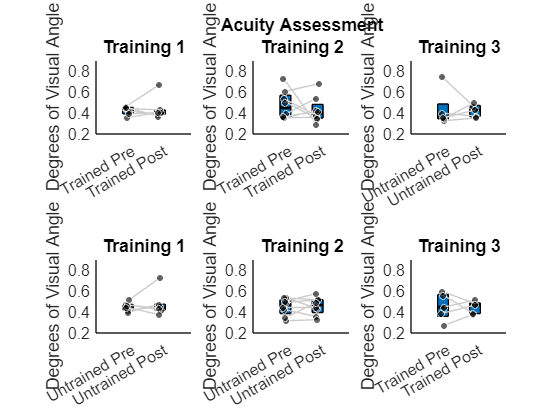

% create label names for each condition of data

condition_names = {'Trained Pre', 'Trained Post','Untrained Pre', 'Untrained Post'};
f1 = figure;

% plots are 2 x 3: 3 trained conditions on top, 3 untrained conditions on
% bottom

subplot(2, 3, 1)

% load in pre and post data for each training type (this is repeated in
% every subplot)

AcuityTrainedTT1(:,1) = cell2mat({DataTableAcuityTT1{:,2}});
AcuityTrainedTT1(:,2) = cell2mat({DataTableAcuityTT1{:,4}});

% plot the data as pre vs post, using scatter to present individual datapoints, and using the 'withinlines' tag to show
% individual differences between groups

j1 = daboxplot(AcuityTrainedTT1,'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Degrees of Visual Angle')
title([newline 'Training 1'])
ylim([0.2 0.9])


subplot(2, 3, 2)
AcuityTrainedTT2(:,1) = cell2mat({DataTableAcuityTT2{:,2}});
AcuityTrainedTT2(:,2) = cell2mat({DataTableAcuityTT2{:,4}});


j2 = daboxplot(AcuityTrainedTT2,'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Degrees of Visual Angle')
title(['Acuity Assessment' newline 'Training 2'])
ylim([0.2 0.9])

subplot(2, 3, 3)
AcuityTrainedTT3(:,1) = cell2mat({DataTableAcuityTT3{:,2}});
AcuityTrainedTT3(:,2) = cell2mat({DataTableAcuityTT3{:,4}});


j3 = daboxplot(AcuityTrainedTT3,'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Degrees of Visual Angle')
title([newline 'Training 3'])
ylim([0.2 0.9])

subplot(2, 3, 4)


AcuityUntrainedTT1(:,1) = cell2mat({DataTableAcuityTT1{:,3}});
AcuityUntrainedTT1(:,2) = cell2mat({DataTableAcuityTT1{:,5}});


j4 = daboxplot(AcuityUntrainedTT1,'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Degrees of Visual Angle')
title([newline 'Training 1'])
ylim([0.2 0.9])


subplot(2, 3, 5)
AcuityUntrainedTT2(:,1) = cell2mat({DataTableAcuityTT2{:,3}});
AcuityUntrainedTT2(:,2) = cell2mat({DataTableAcuityTT2{:,5}});


j5 = daboxplot(AcuityUntrainedTT2,'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Degrees of Visual Angle')
title([newline 'Training 2'])
ylim([0.2 0.9])


subplot(2, 3, 6)
AcuityUntrainedTT3(:,1) = cell2mat({DataTableAcuityTT3{:,3}});
AcuityUntrainedTT3(:,2) = cell2mat({DataTableAcuityTT3{:,5}});


j6 = daboxplot(AcuityUntrainedTT3,'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Degrees of Visual Angle')
title([newline 'Training 3'])
ylim([0.2 0.9])


% As a note, you probabably want to pop these out in a new window for
% better viewing.



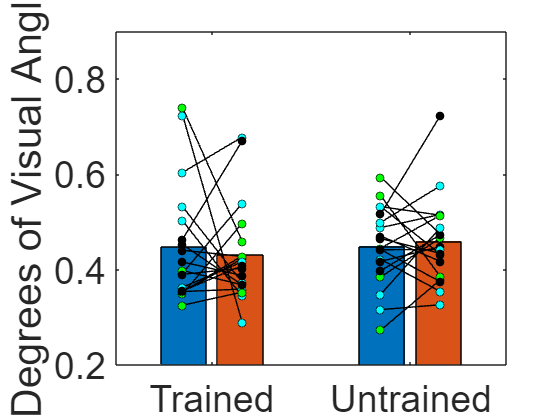

figure;

groupNames = {'Trained', 'Untrained'};
AcuityTotal = [mean(cell2mat(DataTableAcuity(:,[2,4])));
    mean(cell2mat(DataTableAcuity(:,[3,5])))];

AcuityTrained = cell2mat(DataTableAcuity(:,[2,4]));
AcuityUntrained = cell2mat(DataTableAcuity(:,[3,5]));

bar(AcuityTotal, 'grouped');
set(gca,'XTickLabel',groupNames);
ylabel('Degrees of Visual Angle')
ylim([0.2 0.9])

hold on;



for i = 1:size(AcuityTrained,1)
    if string(DataTableAcuity(i,6)) == "1"

        plot([0.85 1.15], [AcuityTrained(i,1) AcuityTrained(i,2)],'k-')
        plot([1.85 2.15], [AcuityUntrained(i,1) AcuityUntrained(i,2)],'k-')

        scatter((1-0.15),AcuityTrained(i,1),'filled','MarkerFaceColor','k','MarkerEdgeColor','k');
        scatter((1+0.15),AcuityTrained(i,2),'filled','MarkerFaceColor','k','MarkerEdgeColor','k');

        scatter((2-0.15),AcuityUntrained(i,1),'filled','MarkerFaceColor','k','MarkerEdgeColor','k');
        scatter((2+0.15),AcuityUntrained(i,2),'filled','MarkerFaceColor','k','MarkerEdgeColor','k');

        

    elseif string(DataTableAcuity(i,6)) == "2"

        plot([0.85 1.15], [AcuityTrained(i,1) AcuityTrained(i,2)],'k-')
        plot([1.85 2.15], [AcuityUntrained(i,1) AcuityUntrained(i,2)],'k-')

        scatter((1-0.15),AcuityTrained(i,1),'filled','MarkerFaceColor','c','MarkerEdgeColor','k');
        scatter((1+0.15),AcuityTrained(i,2),'filled','MarkerFaceColor','c','MarkerEdgeColor','k');

        scatter((2-0.15),AcuityUntrained(i,1),'filled','MarkerFaceColor','c','MarkerEdgeColor','k');
        scatter((2+0.15),AcuityUntrained(i,2),'filled','MarkerFaceColor','c','MarkerEdgeColor','k');

        

    elseif string(DataTableAcuity(i,6)) == "3"

        plot([0.85 1.15], [AcuityTrained(i,1) AcuityTrained(i,2)],'k-')
        plot([1.85 2.15], [AcuityUntrained(i,1) AcuityUntrained(i,2)],'k-')

        scatter((1-0.15),AcuityTrained(i,1),'filled','MarkerFaceColor','g','MarkerEdgeColor','k');
        scatter((1+0.15),AcuityTrained(i,2),'filled','MarkerFaceColor','g','MarkerEdgeColor','k');

        scatter((2-0.15),AcuityUntrained(i,1),'filled','MarkerFaceColor','g','MarkerEdgeColor','k');
        scatter((2+0.15),AcuityUntrained(i,2),'filled','MarkerFaceColor','g','MarkerEdgeColor','k');

        
    end

end

set(gca,'FontSize',28);
AcuityUntrainedEffect = cell2mat(DataTableAcuity(:,5)) - cell2mat(DataTableAcuity(:,3));

AcuityTrainedEffect = cell2mat(DataTableAcuity(:,4)) - cell2mat(DataTableAcuity(:,2));


[hAcuityTE, pAcuityTE, ciAcuityTE, statsAcuityTE] = ttest(AcuityTrainedEffect,AcuityUntrainedEffect);
[hAcuityTPP, pAcuityTPP, ciAcuityTPP, statsAcuityTPP] = ttest(cell2mat(DataTableAcuity(:,2)),cell2mat(DataTableAcuity(:,4)));
[hAcuityUPP, pShpUPP, ciAcuityUPP, statsAcuityUPP] = ttest(cell2mat(DataTableAcuity(:,3)),cell2mat(DataTableAcuity(:,5)));


columnNames =  {'Subject ID', 'Trained Pre', 'Untrained Pre','Trained Post', 'Untrained Post','Training Type'};
DataTableAcuity_table = cell2table(DataTableAcuity,'VariableNames',columnNames);
writetable(DataTableAcuity_table, [SubjectDirectory 'DataTableAcuity.csv']);